# Problema 1 - Practic

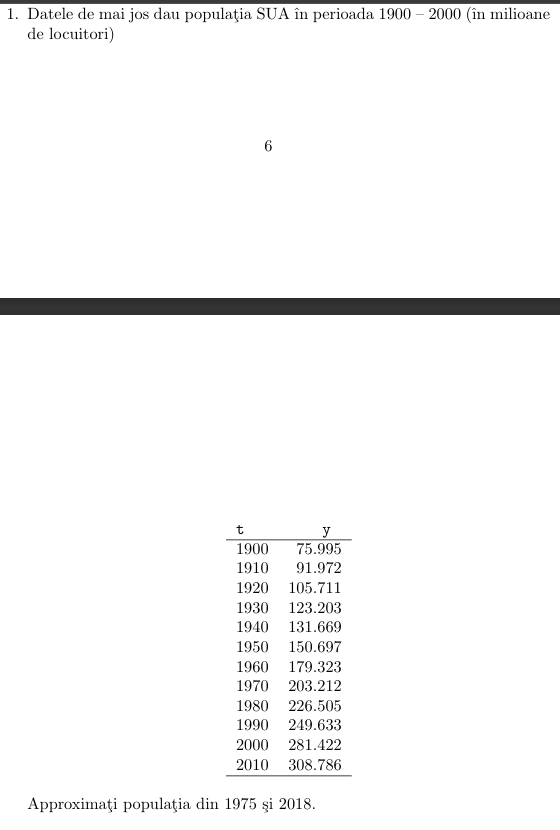

t = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];

ani = [1975, 2018];  % 1975 e pentru interpolare, 2018 pentru extrapolare

%PB1
function [p_val, p_expr] = lagrangeInterpolation(x_nodes, y_nodes, x_eval)
% INPUT:
%   x_nodes  - vectorul nodurilor de interpolare 
%   y_nodes  - vectorul valorilor functiei in noduri 
%   x_eval   - vectorul punctelor in care se evalueaza polinomul
%
% OUTPUT:
%   p_val    - valorile numerice ale polinomului in punctele x_eval
%   p_expr   - expresia simbolica a polinomului
 
    % Numarul de noduri
    n = length(x_nodes);

    % Asiguram ca x_eval este coloana
    x_eval = x_eval(:);

    % Initializam vectorul rezultat
    p_val = zeros(size(x_eval));

    % Initializare variabila simbolica si polinom simbolic
    syms x;
    p_expr = 0;

    % Construim expresia simbolica si evaluam numeric
    for i = 1:n
        % Initializare L_i(x)
        L_i = 1;
        for j = 1:n
            if j ~= i
                L_i = L_i * (x - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
            end
        end
        % Adunam termenul y_i * L_i(x)
        p_expr = p_expr + y_nodes(i) * L_i;
    end

    % Evaluam numeric in punctele dorite
    for k = 1:length(x_eval)
        p_val(k) = double(subs(p_expr, x, x_eval(k)));
    end

    % Simplificam 
    p_expr = expand(p_expr);  % dezvoltare
end

p_val, p_expr = lagrangeInterpolation(t, y, ani);

p_val =   -29.0000
  -28.5077
  -28.0207
  -27.5391
  -27.0627
  -26.5916
  -26.1257
  -25.6650
  -25.2095
  -24.7591



fprintf('Populația aproximativă în 1975: %.3f milioane locuitori\n', p_val(1));

Populația aproximativă în 1975: -29.000 milioane locuitori


fprintf('Populația aproximativă în 2018: %.3f milioane locuitori\n', p_val(2));

Populația aproximativă în 2018: -28.508 milioane locuitori
